A = 1; % Signal amplitude
N = 10; % Temporal samples
M = 10; % Spatial samples
fr = 1e6; % Continuous frequency (Hz)
fs = 1e7; % Sampling frequency (Hz)
H = 2 * pi * fr * (1/fs); % Discrete angular frequency (rad/samp.)
itr = 1000; % iterations to calculate MLE variance
K = 1000; % Angle resolution
% covr = sg * eye(M); % Covariance matrix 
% detr = (-N/2) * log(det(2 * pi * covr)); % Derterminant term for the likelihood sum
theta_values = linspace(-pi/2, pi/2, K); % Angle values
sgVals = linspace(1, 0.001, K);
%%%%%% Deterministic signal from equidistant antenna elements
x1_n = zeros(M, N, K); 
[i, j] = meshgrid(1:N, 1:M);
for k = 1:K
    x1_n(:,:,k) = A * cos(H * i + (j - 1) * pi * sin(theta_values(k)));
end

sg = 0.1;
CRLB_1 = zeros(1,K);
    for u = 1 : K
        R = 0;
        for k = 1 : N
            for l = 1 : M
                R = R + (pi^2 * (A^2 / sg) * (l - 1)^2 * (sin((H * k)+((l - 1)* pi * sin(theta_values(u)))))^2 * (cos(theta_values(u)))^2);
            end
        end
        CRLB_1(u) = 1 / R;
    end
 CRLB_Q1 = zeros(1,K);
    for u = 1 : K
        result = 0;
        for k = 1 : N
            for l = 1 : M
                cd = normcdf(-x1_n(l, k, u)/sqrt(sg));
                cd2 = normcdf(-x1_n(l, k, u)/sqrt(sg), 'upper');
                pd = normpdf(-x1_n(l, k, u)/sqrt(sg));
                phi = cd - cd^2;
                G = (1/cd) * pd * (A/sqrt(sg)) * (l - 1) * pi * cos(theta_values(u)) * sin((H * k) + ((l - 1) * pi * sin(theta_values(u))));
                J = (1/(cd2)) * pd * (A/sqrt(sg)) * (l - 1) * pi * cos(theta_values(u)) * sin((H * k) + ((l - 1) * pi * sin(theta_values(u))));
                result = result + (phi * (G + J)^2);
            end
        end
        CRLB_Q1(u) = 1 / result;
    end

sg = 1;
CRLB_2 = zeros(1,K);
    for u = 1 : K
        R = 0;
        for k = 1 : N
            for l = 1 : M
                R = R + (pi^2 * (A^2 / sg) * (l - 1)^2 * (sin((H * k)+((l - 1)* pi * sin(theta_values(u)))))^2 * (cos(theta_values(u)))^2);
            end
        end
        CRLB_2(u) = 1 / R;
    end
 CRLB_Q2 = zeros(1,K);
    for u = 1 : K
        result = 0;
        for k = 1 : N
            for l = 1 : M
                cd = normcdf(-x1_n(l, k, u)/sqrt(sg));
                cd2 = normcdf(-x1_n(l, k, u)/sqrt(sg), 'upper');
                pd = normpdf(-x1_n(l, k, u)/sqrt(sg));
                phi = cd - cd^2;
                G = (1/cd) * pd * (A/sqrt(sg)) * (l - 1) * pi * cos(theta_values(u)) * sin((H * k) + ((l - 1) * pi * sin(theta_values(u))));
                J = (1/(cd2)) * pd * (A/sqrt(sg)) * (l - 1) * pi * cos(theta_values(u)) * sin((H * k) + ((l - 1) * pi * sin(theta_values(u))));
                result = result + (phi * (G + J)^2);
            end
        end
        CRLB_Q2(u) = 1 / result;
    end

sg = 10;
CRLB_3 = zeros(1,K);
    for u = 1 : K
        R = 0;
        for k = 1 : N
            for l = 1 : M
                R = R + (pi^2 * (A^2 / sg) * (l - 1)^2 * (sin((H * k)+((l - 1)* pi * sin(theta_values(u)))))^2 * (cos(theta_values(u)))^2);
            end
        end
        CRLB_3(u) = 1 / R;
    end
 CRLB_Q3 = zeros(1,K);
    for u = 1 : K
        result = 0;
        for k = 1 : N
            for l = 1 : M
                cd = normcdf(-x1_n(l, k, u)/sqrt(sg));
                cd2 = normcdf(-x1_n(l, k, u)/sqrt(sg), 'upper');
                pd = normpdf(-x1_n(l, k, u)/sqrt(sg));
                phi = cd - cd^2;
                G = (1/cd) * pd * (A/sqrt(sg)) * (l - 1) * pi * cos(theta_values(u)) * sin((H * k) + ((l - 1) * pi * sin(theta_values(u))));
                J = (1/(cd2)) * pd * (A/sqrt(sg)) * (l - 1) * pi * cos(theta_values(u)) * sin((H * k) + ((l - 1) * pi * sin(theta_values(u))));
                result = result + (phi * (G + J)^2);
            end
        end
        CRLB_Q3(u) = 1 / result;
    end

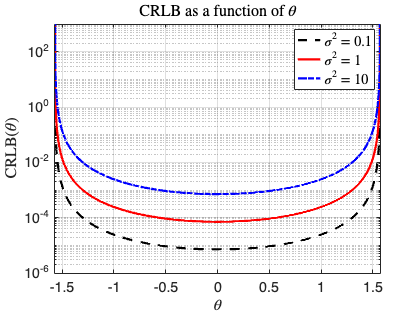

figure;
semilogy(theta_values, CRLB_1, 'k--', theta_values, CRLB_2, 'r', theta_values, CRLB_3, 'b-.', LineWidth=3);
xlim([-pi/2 pi/2]);
ylim([10^(-6) 10^3]);
title('CRLB as a function of $\theta$', 'FontSize', 18, Interpreter='latex');
xlabel('$\theta$', 'FontSize', 18, Interpreter='latex');
ylabel('CRLB$(\theta)$', 'FontSize', 18, Interpreter='latex');
legend(["$\sigma^2=0.1$","$\sigma^2=1$","$\sigma^2=10$"], 'FontSize', 18, Interpreter='latex')
grid on
set(gca,"FontSize",19);

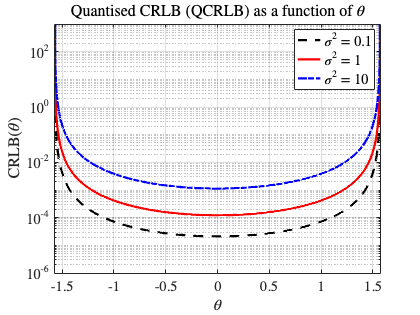

figure;
semilogy(theta_values, CRLB_Q1, 'k--', theta_values, CRLB_Q2, 'r', theta_values, CRLB_Q3, 'b-.', LineWidth=3);
xlim([-pi/2 pi/2]);
ylim([10^(-6) 10^3]);
title('Quantised CRLB (QCRLB) as a function of $\theta$', 'FontSize', 18, Interpreter='latex');
xlabel('$\theta$', 'FontSize', 18, Interpreter='latex');
ylabel('CRLB$(\theta)$', 'FontSize', 18, Interpreter='latex');
legend(["$\sigma^2=0.1$","$\sigma^2=1$","$\sigma^2=10$"], 'FontSize', 18,Interpreter='latex')
grid on
set(gca,"FontSize",19,'FontName','cmr12');

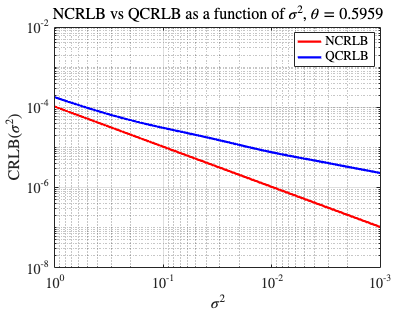

K = 1000;
CRLB_sg2 = zeros(1,K);
    for u = 1 : K
        R = 0;
        for k = 1 : N
            for l = 1 : M
                R = R + (pi^2 * (A^2 / sgVals(u)) * (l - 1)^2 * (sin((H * k)+((l - 1)* pi * sin(0.5959))))^2 * (cos(0.5959))^2);
            end
        end
        CRLB_sg2(u) = 1 / R;
    end
 CRLB_Qsg2 = zeros(1,K);
    for u = 1 : K
        result = 0;
        for k = 1 : N
            for l = 1 : M
                cd = normcdf(-x1_n(l, k, 690)/sqrt(sgVals(u)));
                cd2 = normcdf(-x1_n(l, k, 690)/sqrt(sgVals(u)), 'upper');
                pd = normpdf(-x1_n(l, k, 690)/sqrt(sgVals(u)));
                phi = cd - cd^2;
                G = (1/cd) * pd * (A/sqrt(sgVals(u))) * (l - 1) * pi * cos(0.5959) * sin((H * k) + ((l - 1) * pi * sin(0.5959)));
                J = (1/(cd2)) * pd * (A/sqrt(sgVals(u))) * (l - 1) * pi * cos(0.5959) * sin((H * k) + ((l - 1) * pi * sin(0.5959)));
                result = result + (phi * (G + J)^2);
            end
        end
        CRLB_Qsg2(u) = 1 / result;
    end
figure;
loglog(sgVals, CRLB_sg2, 'r', sgVals, CRLB_Qsg2, 'b', LineWidth=3);
set( gca, 'xdir', 'reverse' );
title('NCRLB  vs QCRLB as a function of $\sigma^2$, $\theta = 0.5959$', 'FontSize', 14, Interpreter='latex');
xlabel('$\sigma^2$', 'FontSize', 14, Interpreter='latex');
ylabel('CRLB$(\sigma^2)$', 'FontSize', 14, Interpreter='latex');
ylim([10^(-8) 10^(-2)])
grid on
set(gca,"FontSize",19,'FontName','cmr12');

legend(["NCRLB","QCRLB"], Interpreter='latex')

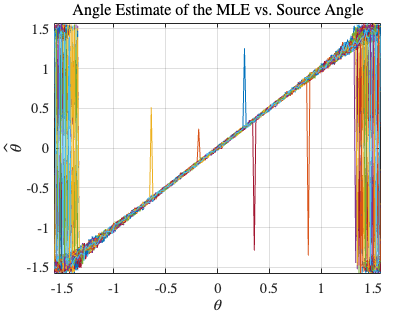

sg = 1;
itr = 1000; % iterations to calculate MLE variance
K = 200; % Angle resolution
covr = sg * eye(M); % Covariance matrix 
detr = (-N/2) * log(det(2 * pi * covr)); % Derterminant term for the likelihood sum
theta_values = linspace(-pi/2, pi/2, K); 
x_n = zeros(M, N, K); 
[i, j] = meshgrid(1:N, 1:M);

for k = 1:K
    x_n(:,:,k) = A * cos(H * i + (j - 1) * pi * sin(theta_values(k)));
end
llh = zeros(1, K); % Creating zero vector for log-likelihood function
argm = zeros(K, itr); % Creating a matrix for the arg max, holding arg max values for all iterations and angles.
for l = 1 : K % Source angle
    for v = 1 : itr % Iteration
        y_n = x_n(:, :, l) + (sqrt(sg) * randn(M, N)); % Constructing y_n for a source angle ('l' selects the "page" and hence the angle).
        for d = 1 : K % Calculating log likelihood for all angles
            diff = y_n - x_n(:, :, d);
            sumTerm = sum(diff.*((1/sg)*diff), "all");
            llh(d) = detr + (-0.5) * sumTerm;
        end
        [~, indx] = max(llh); % Finding a max in the iteration, for the angle.
        argm(l, v) = theta_values(indx);% Filling in the iteration in argm.
    end
end
figure;
plot(theta_values, argm);
title('Angle Estimate of the MLE vs. Source Angle', 'FontSize', 18, Interpreter='latex');
xlabel('$\theta$', 'FontSize', 18, Interpreter='latex');
ylabel('$\hat{\theta}$', 'FontSize', 18, Interpreter='latex');
xlim([-pi/2 pi/2])
ylim([-pi/2 pi/2])
set(gca,"FontSize",19,'FontName','cmr12');
grid on

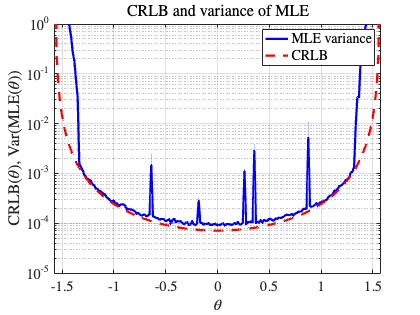

VARMLE = zeros(1, K);
for u = 1 : K
    VARMLE(u) = var(argm(u, :));
end
 CR = zeros(1,K);
    for u = 1 : K
        R = 0;
        for k = 1 : N
            for l = 1 : M
                R = R + (pi^2 * (A^2 / sg) * (l - 1)^2 * (sin((H * k)+((l - 1)* pi * sin(theta_values(u)))))^2 * (cos(theta_values(u)))^2);
            end
        end
        CR(u) = 1 / R;
    end
figure;
semilogy(theta_values,VARMLE, 'b', theta_values, CR, 'r--', LineWidth=3);
xlim([-pi/2 pi/2]);
ylim([10^-5 10^0]);
title('CRLB and variance of MLE', 'FontSize', 18, Interpreter='latex');
xlabel('$\theta$', 'FontSize', 18, Interpreter='latex');
ylabel('$\mathrm{CRLB}(\theta)$, $\mathrm{Var}(\mathrm{MLE}(\theta))$', 'FontSize', 18, Interpreter='latex');
grid on
legend(["MLE variance","CRLB"], Interpreter="latex", FontSize=18)
set(gca,"FontSize",19,'FontName','cmr12');

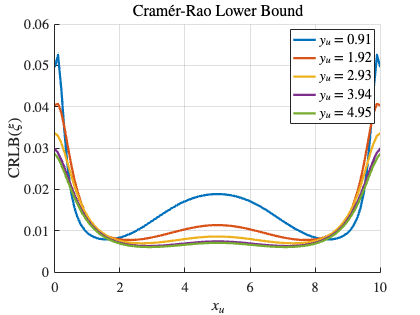

K = 4; % Number of Sensor Arrays
SqSize = 10; % Localisation grid size
ArrLoc = [0 0 SqSize SqSize; 0 SqSize 0 SqSize]; % Array locations [(0,0), (0,x), (x,0), (x,x)]
A = 1; % Constant signal amplitude
sgSq = 1; % Noise Variance
% Setting object locations
LocRes = 100; % Location resolution per axis
x_u = linspace(0, SqSize, LocRes); % X Locations
y_u = linspace(0, SqSize, LocRes); % Y Locations
f_c = 1e6; % Continuous Signal Frequency 
f_s = 1e7; % Sampling frequency 
H = 2 * pi * f_c * (1/f_s); % Discrete Angular Frequency;
N = 10; % Temporal Samples
M = 10; % Spatial Samples


J_inv = zeros(2, 2, LocRes, LocRes);

for i = 1 : LocRes
    for j = 1 : LocRes
        P = 0;
        Q = 0;
        R = 0;

        for k = 1 : K
            for n = 1 : N
                for m = 1 : M

                    P = P + ( (A^2/sgSq) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))^2 * ((y_u(j) - ArrLoc(2,k))^2/((y_u(j) - ArrLoc(2,k))^2 + (x_u(i) - ArrLoc(1,k))^2)^2));
                    Q = Q + ( (A^2/sgSq) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))^2 * ((x_u(i) - ArrLoc(1,k))^2/((y_u(j) - ArrLoc(2,k))^2 + (x_u(i) - ArrLoc(1,k))^2)^2));
                    R = R + ( (A^2/sgSq) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))^2 * ((-1) * (x_u(i) - ArrLoc(1,k)) * (y_u(j) - ArrLoc(2,k))/((y_u(j) - ArrLoc(2,k))^2 + (x_u(i) - ArrLoc(1,k))^2)^2));

                end
            end
        end

        J = [P R; R Q];
        J_inv(:, :, i, j) = inv(J);

    end
end

MSE_CRLB = zeros(LocRes, LocRes);
  for i = 1 : LocRes 
    for j = 1 : LocRes
        MSE_CRLB(i, j) = trace(J_inv(:, :, i, j));
    end
  end
S = zeros(1, LocRes/10);
S = string(S);
figure;
hold on
for j = 1 : 1 : 5
    plot(x_u, MSE_CRLB(:, j*10), LineWidth=3);
    S(j) = ['$y_u$ = ' num2str(round(y_u(j*10),2))];
end
hold off;
title("Cram\'er-Rao Lower Bound", Interpreter="latex", FontSize=18);
xlabel("$x_u$", Interpreter="latex", FontSize=18);
ylabel("CRLB$(\xi)$", Interpreter="latex", FontSize=18);
legend(S, 'Interpreter','latex', FontSize=18);
grid on;
set(gca,"FontSize",19,'FontName','cmr12');

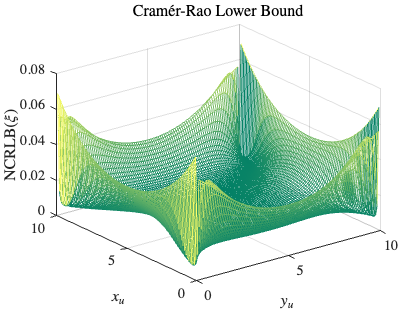

s = figure;
mesh(x_u, y_u, MSE_CRLB,'FaceAlpha','0.1');
title("Cram\'er-Rao Lower Bound", Interpreter="latex", FontSize=18);
xlabel("$y_u$", Interpreter="latex", FontSize=18);
ylabel("$x_u$", Interpreter="latex", FontSize=18);
zlabel("NCRLB$(\xi)$", Interpreter="latex", FontSize=18);
colormap(s,'summer')
set(gca,'ZScale','linear', "FontSize",19,'FontName','cmr12');
grid on;
hidden off;

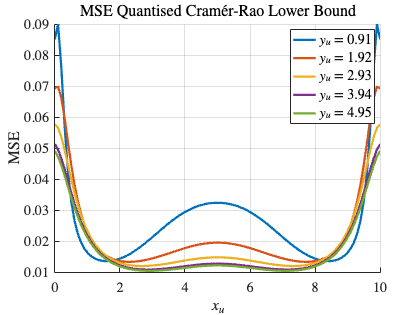

figure;
J_inv_Q = zeros(2, 2, LocRes, LocRes);

for i = 1 : LocRes
    for j = 1 : LocRes
        P = 0;
        Q = 0;
        R = 0;

        for k = 1 : K
            for n = 1 : N
                for m = 1 : M
                    p = normcdf(-(A * cos((H * n)+((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))/sqrt(sgSq), 'upper');
                    q = normcdf(-(A * cos((H * n)+((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))/sqrt(sgSq));
                    F = normpdf(-(A * cos((H * n)+((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))/sqrt(sgSq));
                    P = P + ((1/(p*q))* F^2 *( (A^2/sgSq) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))^2 * ((y_u(j) - ArrLoc(2,k))^2/((y_u(j) - ArrLoc(2,k))^2 + (x_u(i) - ArrLoc(1,k))^2)^2)));
                    Q = Q + ((1/(p*q))* F^2 *( (A^2/sgSq) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))^2 * ((x_u(i) - ArrLoc(1,k))^2/((y_u(j) - ArrLoc(2,k))^2 + (x_u(i) - ArrLoc(1,k))^2)^2)));
                    R = R + ((1/(p*q))* F^2 *( (A^2/sgSq) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))^2 * ((-1) * (x_u(i) - ArrLoc(1,k)) * (y_u(j) - ArrLoc(2,k))/((y_u(j) - ArrLoc(2,k))^2 + (x_u(i) - ArrLoc(1,k))^2)^2)));

                end
            end
        end

        J = [P R; R Q];
        J_inv_Q(:, :, i, j) = inv(J);

    end
end

MSE_CRLB_Q = zeros(LocRes, LocRes);
  for i = 1 : LocRes 
    for j = 1 : LocRes
        MSE_CRLB_Q(i, j) = trace(J_inv_Q(:, :, i, j));
    end
  end
S2 = zeros(1, LocRes/10);
S2 = string(S2);
figure;
hold on
for j = 1 : 1 : 5
    plot(x_u, MSE_CRLB_Q(:, j*10), LineWidth=3);
    S2(j) = ['$y_u$ = ' num2str(round(y_u(j*10),2))];
end
hold off;
title("MSE Quantised Cram\'er-Rao Lower Bound", Interpreter="latex", FontSize=18);
xlabel("$x_u$", Interpreter="latex", FontSize=18);
ylabel("MSE", Interpreter="latex", FontSize=18);
legend(S2, 'Interpreter','latex', FontSize=18);
grid on;
set(gca,"FontSize",19,'FontName','cmr12');

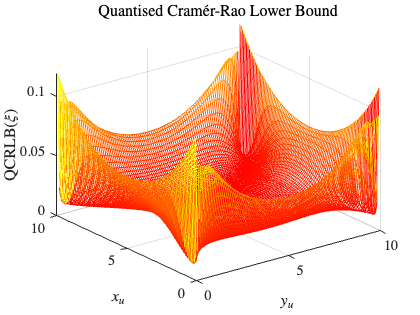

s2 = figure;
mesh(x_u, y_u, MSE_CRLB_Q,'FaceAlpha','0.1');
title("Quantised Cram\'er-Rao Lower Bound", Interpreter="latex", FontSize=18);
xlabel("$y_u$", Interpreter="latex", FontSize=18);
ylabel("$x_u$", Interpreter="latex", FontSize=18);
zlabel("QCRLB$(\xi)$", Interpreter="latex", FontSize=18);
colormap(s2,'autumn')
set(gca,'ZScale','linear',"FontSize",19,'FontName','cmr12');
grid on;
hidden off;

sgSq = 0.1;
J_inv = zeros(2, 2, LocRes, LocRes);

for i = 1 : LocRes
    for j = 1 : LocRes
        P = 0;
        Q = 0;
        R = 0;

        for k = 1 : K
            for n = 1 : N
                for m = 1 : M

                    P = P + ( (A^2/sgSq) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))^2 * ((y_u(j) - ArrLoc(2,k))^2/((y_u(j) - ArrLoc(2,k))^2 + (x_u(i) - ArrLoc(1,k))^2)^2));
                    Q = Q + ( (A^2/sgSq) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))^2 * ((x_u(i) - ArrLoc(1,k))^2/((y_u(j) - ArrLoc(2,k))^2 + (x_u(i) - ArrLoc(1,k))^2)^2));
                    R = R + ( (A^2/sgSq) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))^2 * ((-1) * (x_u(i) - ArrLoc(1,k)) * (y_u(j) - ArrLoc(2,k))/((y_u(j) - ArrLoc(2,k))^2 + (x_u(i) - ArrLoc(1,k))^2)^2));

                end
            end
        end

        J = [P R; R Q];
        J_inv(:, :, i, j) = inv(J);

    end
end

MSE_CRLB_2 = zeros(LocRes, LocRes);
  for i = 1 : LocRes 
    for j = 1 : LocRes
        MSE_CRLB_2(i, j) = trace(J_inv(:, :, i, j));
    end
  end


J_inv_Q = zeros(2, 2, LocRes, LocRes);

for i = 1 : LocRes
    for j = 1 : LocRes
        P = 0;
        Q = 0;
        R = 0;

        for k = 1 : K
            for n = 1 : N
                for m = 1 : M
                    p = normcdf(-(A * cos((H * n)+((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))/sqrt(sgSq), 'upper');
                    q = normcdf(-(A * cos((H * n)+((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))/sqrt(sgSq));
                    F = normpdf(-(A * cos((H * n)+((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))/sqrt(sgSq));
                    P = P + ((1/(p*q))* F^2 *( (A^2/sgSq) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))^2 * ((y_u(j) - ArrLoc(2,k))^2/((y_u(j) - ArrLoc(2,k))^2 + (x_u(i) - ArrLoc(1,k))^2)^2)));
                    Q = Q + ((1/(p*q))* F^2 *( (A^2/sgSq) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))^2 * ((x_u(i) - ArrLoc(1,k))^2/((y_u(j) - ArrLoc(2,k))^2 + (x_u(i) - ArrLoc(1,k))^2)^2)));
                    R = R + ((1/(p*q))* F^2 *( (A^2/sgSq) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(i)-ArrLoc(1,k))/(y_u(j)-ArrLoc(2,k)))))^2 * ((-1) * (x_u(i) - ArrLoc(1,k)) * (y_u(j) - ArrLoc(2,k))/((y_u(j) - ArrLoc(2,k))^2 + (x_u(i) - ArrLoc(1,k))^2)^2)));

                end
            end
        end

        J = [P R; R Q];
        J_inv_Q(:, :, i, j) = inv(J);

    end
end

MSE_CRLB_Q_2 = zeros(LocRes, LocRes);
  for i = 1 : LocRes 
    for j = 1 : LocRes
        MSE_CRLB_Q_2(i, j) = trace(J_inv_Q(:, :, i, j));
    end
  end


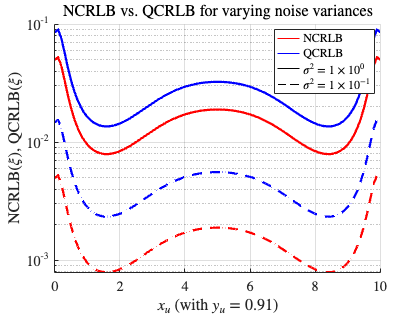

figure;
hold on
plot(x_u, MSE_CRLB(:, 10), "r", x_u, MSE_CRLB_Q(:, 10), "b", x_u, MSE_CRLB_2(:, 10), "r--", x_u, MSE_CRLB_Q_2(:, 10), "b--", LineWidth=3);
title("NCRLB vs. QCRLB for varying noise variances", Interpreter="latex", FontSize=18);
xlabel("$x_u$ (with $y_u = 0.91)$", Interpreter="latex", FontSize=18);
ylabel("NCRLB$(\xi)$, QCRLB$(\xi)$", Interpreter="latex", FontSize=18);
set(gca, 'YScale', 'log')
qw{1} = plot(nan, 'r-');
qw{2} = plot(nan, 'b-');
qw{3} = plot(nan, 'k-');
qw{4} = plot(nan, 'k--');
legend([qw{:}], {'NCRLB','QCRLB','$\sigma^2 = 1\times 10^0$', '$\sigma^2 = 1\times 10^{-1}$'}, 'Interpreter','latex', FontSize=16);
grid on
hold off
set(gca,"FontSize",19,'FontName','cmr12');

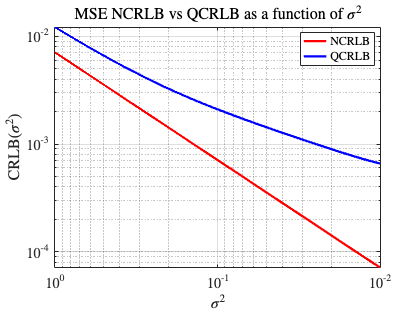

sgSqVals = linspace(1, 0.01, 1000);

J_inv = zeros(2, 2, 1000);

    for u = 1 : 1000
        
        P = 0;
        Q = 0;
        R = 0;

        for k = 1 : K
            for n = 1 : N
                for m = 1 : M

                    P = P + ( (A^2/sgSqVals(u)) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))^2 * ((y_u(50) - ArrLoc(2,k))^2/((y_u(50) - ArrLoc(2,k))^2 + (x_u(50) - ArrLoc(1,k))^2)^2));
                    Q = Q + ( (A^2/sgSqVals(u)) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))^2 * ((x_u(50) - ArrLoc(1,k))^2/((y_u(50) - ArrLoc(2,k))^2 + (x_u(50) - ArrLoc(1,k))^2)^2));
                    R = R + ( (A^2/sgSqVals(u)) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))^2 * ((-1) * (x_u(50) - ArrLoc(1,k)) * (y_u(50) - ArrLoc(2,k))/((y_u(50) - ArrLoc(2,k))^2 + (x_u(50) - ArrLoc(1,k))^2)^2));

                end
            end
        end

        J = [P R; R Q];
        J_inv(:, :, u) = inv(J);

    end


MSE_CRLB_Var = zeros(1, 1000);
  for u = 1 : 1000
        MSE_CRLB_Var(u) = trace(J_inv(:, :, u));
  end
 
J_inv_Q = zeros(2, 2, 1000);


    for u = 1 : 1000
        P = 0;
        Q = 0;
        R = 0;

        for k = 1 : K
            for n = 1 : N
                for m = 1 : M
                    p = normcdf(-(A * cos((H * n)+((m - 1) * pi * sin(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))))/sqrt(sgSqVals(u)), 'upper');
                    q = normcdf(-(A * cos((H * n)+((m - 1) * pi * sin(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))))/sqrt(sgSqVals(u)));
                    F = normpdf(-(A * cos((H * n)+((m - 1) * pi * sin(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))))/sqrt(sgSqVals(u)));
                    P = P + ((1/(p*q))* F^2 *( (A^2/sgSqVals(u)) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))^2 * ((y_u(50) - ArrLoc(2,k))^2/((y_u(50) - ArrLoc(2,k))^2 + (x_u(50) - ArrLoc(1,k))^2)^2)));
                    Q = Q + ((1/(p*q))* F^2 *( (A^2/sgSqVals(u)) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))^2 * ((x_u(50) - ArrLoc(1,k))^2/((y_u(50) - ArrLoc(2,k))^2 + (x_u(50) - ArrLoc(1,k))^2)^2)));
                    R = R + ((1/(p*q))* F^2 *( (A^2/sgSqVals(u)) * (sin( (H * n) + ((m - 1) * pi * sin(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))))^2  * (m - 1)^2 * pi^2 * (cos(atan((x_u(50)-ArrLoc(1,k))/(y_u(50)-ArrLoc(2,k)))))^2 * ((-1) * (x_u(50) - ArrLoc(1,k)) * (y_u(50) - ArrLoc(2,k))/((y_u(50) - ArrLoc(2,k))^2 + (x_u(50) - ArrLoc(1,k))^2)^2)));

                end
            end
        end

        J = [P R; R Q];
        J_inv_Q(:, :, u) = inv(J);

    end


MSE_CRLB_Q_Var = zeros(1,1000);

    for u = 1 : 1000
        MSE_CRLB_Q_Var(u) = trace(J_inv_Q(:, :, u));
    end

figure;
loglog(sgSqVals, MSE_CRLB_Var, 'r', sgSqVals, MSE_CRLB_Q_Var, 'b', LineWidth=3);
set( gca, 'xdir', 'reverse' );
title(' MSE NCRLB  vs QCRLB as a function of $\sigma^2$', 'FontSize', 18, Interpreter='latex');
xlabel('$\sigma^2$', 'FontSize', 18, Interpreter='latex');
ylabel('CRLB$(\sigma^2)$', 'FontSize', 18, Interpreter='latex');
grid on
legend(["NCRLB","QCRLB"], Interpreter="latex", FontSize=16);
set(gca,"FontSize",19,'FontName','cmr12');